`image augment`

inputSize = net.Layers(1).InputSize

inputSize =    227   227     3


pixelRange = [-30 30];
imageAugmenter = imageDataAugmenter( ...
    'RandXReflection',true, ...
    'RandXTranslation',pixelRange, ...
    'RandYTranslation',pixelRange);
augimdsTrain = augmentedImageDatastore(inputSize(1:2),imdsTrain, ...
    'DataAugmentation',imageAugmenter);
augimdsValidation = augmentedImageDatastore(inputSize(1:2),imdsValidation);

`Specify the options to use during training.`

numEpochs = 8;
miniBatchSize = 10;
%validationFrequency = 3;

`Specify the options for SGDM optimization. Specify an initial learn rate of 1e-3 with a decay of 0.01, and momentum 0.9.`

initialLearnRate = 1e-4;
decay = 0.01;
momentum = 0.9;

`Use the custom mini-batch preprocessing function preprocessMiniBatch (defined at the end of this example) to convert the labels to one-hot encoded variables.`

`Format the image data with the dimension labels "SSCB" (spatial, spatial, channel, batch). `

mbq = minibatchqueue(augimdsTrain,...
    MiniBatchSize=miniBatchSize,...
    MiniBatchFcn=@preprocessMiniBatch,...
    MiniBatchFormat=["SSCB" ""]);
mbqvalid = minibatchqueue(augimdsValidation,...
    MiniBatchSize=miniBatchSize,...
    MiniBatchFcn=@preprocessMiniBatch,...
    MiniBatchFormat=["SSCB" ""]);

`Initialize the velocity parameter for the SGDM solver.`

velocity = [];

`Calculate the total number of iterations for the training progress monitor.`

numObservationsTrain = numel(imdsTrain.Files);
numIterationsPerEpoch = ceil(numObservationsTrain / miniBatchSize);
numIterations = numEpochs * numIterationsPerEpoch;

`Initialize the TrainingProgressMonitor object. Because the timer starts when you create the monitor object, make sure that you create the object close to the training loop.`

monitor = trainingProgressMonitor;
monitor.Info = ["LearningRate","Epoch","Iteration"];
monitor.Metrics = ["TrainingLoss","TrainingAccuracy","ValidationAccuracy"];
monitor.XLabel = "Iteration";
groupSubPlot(monitor,"Loss","TrainingLoss");
groupSubPlot(monitor,"Accuracy",["TrainingAccuracy","ValidationAccuracy"]);

`Train the model using a custom training loop. For each epoch, shuffle the data and loop over mini-batches of data. Update the network parameters using the sgdmupdate function. At the end of each iteration, display the training progress.`

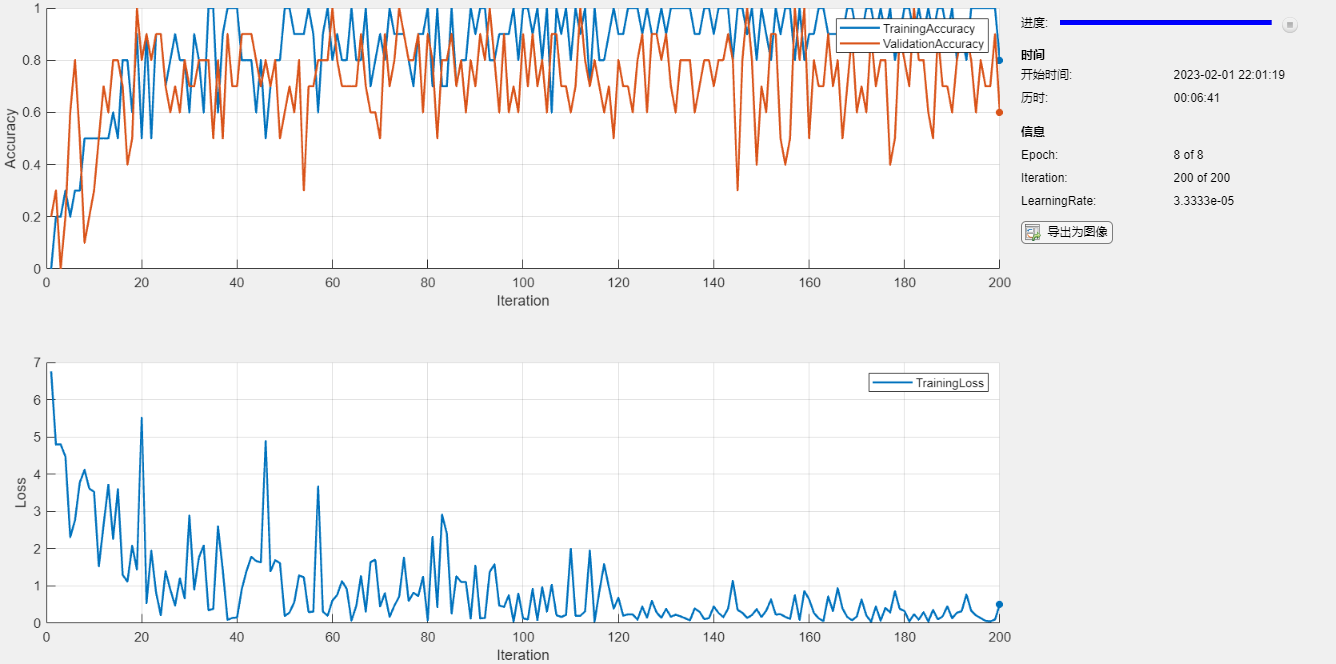

epoch = 0;
iteration = 0;
% Loop over epochs.
while epoch < numEpochs && ~monitor.Stop
    
    epoch = epoch + 1;

    % Shuffle data.
    shuffle(mbq);
    
    % Loop over mini-batches.
    while hasdata(mbq) && ~monitor.Stop

        iteration = iteration + 1;
        
        if ~hasdata(mbqvalid)
            shuffle(mbqvalid);
        end

        % Read mini-batch of data.
        [X,T] = next(mbq);
        [V,VT] = next(mbqvalid);
        
        % Evaluate the model gradients, state, and loss using dlfeval and the
        % modelLoss function and update the network state.
        %(net,X,T,V,VT,labels,gamma,trade_off,miniBatchSize)
        [loss,accuracy,validaccuracy,gradients,state] = dlfeval(@total_loss,net,X,T,V,VT,labels,5,0.1,miniBatchSize);
        net.State = state;

        % Determine learning rate for time-based decay learning rate schedule.
        learnRate = initialLearnRate/(1 + decay*iteration);
        
        % Update the network parameters using the SGDM optimizer.
        [net,velocity] = sgdmupdate(net,gradients,velocity,learnRate,momentum);


        % validation, unlabeled
        %if mod(iteration, validationFrequency) == 0
        %    [V,VT] = next(mbqvalid);
        %    [validLoss,validaccuracy,vgradients,state] = dlfeval(@total_loss,net,V,VT,labels,0,5,0.1,miniBatchSize);
        %    % Update the network parameters using the SGDM optimizer.
        %    [net,velocity] = sgdmupdate(net,vgradients,velocity,learnRate,momentum);
        %end

        %update info for monitor
        updateInfo(monitor, ...
            LearningRate=learnRate, ...
            Epoch=string(epoch) + " of " + string(numEpochs), ...
            Iteration=string(iteration) + " of " + string(numIterations));
        %Update the training progress monitor.)
        %if mod(iteration, validationFrequency) == 0
            recordMetrics(monitor,iteration, ...
                TrainingLoss=loss, ...
                TrainingAccuracy=accuracy, ...
                ValidationAccuracy=validaccuracy);
        %else
        %    recordMetrics(monitor,iteration, ...
        %        TrainingLoss=loss, ...
        %        TrainingAccuracy=accuracy);
        %end
        monitor.Progress = 100 * iteration/numIterations;
    end
end